# A Schrodinger-Poisson problem

Set up a quantum graph in the form of a dumbbell plus one extra unbounded edge

Solve the vertex-value problem 


$$\triangle u - V(x)\, u= f \\
\sum w u'(\mathtt{v_1})+ u(\mathtt{v_1}) = 6 \\
\sum w u'(\mathtt{v_2})+ u(\mathtt{v_2}) = 3\\
u(\mathtt{v_3}) = \sech2
$$


where 

- The potential is $V(x) = \{ 2 \cos{2x},0,0,0,0\}$

- The functions on the right-hand-sides are $f = \left\{
-\sin{3x},
2\cos{2x},
-4,
-\sin{x},
\sech{x}-2 \sech^3{x}
\right\}$on the four edges.

- the edges have lengths $\left\{
\pi, 2\pi,1, 2\pi, 2
\right\}$.

- The exact solutions on the edges are $\left\{
\sin{x},
\sin^2{x},
3x-2x^2,
1+\sin{x},
\sech{x}
\right\}$.

The exact solution is computed in the accompanying Mathematica notebook of the same name.

## Quantum graph definition

s=[1 1 1 2 2];
t=[1 1 2 2 3];
L=[pi 2*pi 1 2*pi 2];
robinCoeff=[1 1 nan];
weight = [1 1 2 1 1];

## The exact solution

u1=@(x)sin(x);
u2=@(x)sin(x).^2;
u3=@(x)(3*x-2*x.^2);
u4=@(x)(1+sin(x));
u5=@(x)sech(x);

## The right hand sides

Edges and nodes

f1=@(x)-sin(3*x);
f2=@(x)2*cos(2*x);
f3=-4;
f4=@(x)-sin(x);
f5=@(x)sech(x).*(1-2*sech(x).^2);
nodeData = [8;3;sech(2)];

## The potential

potentialV = {@(x)(2*cos(2*x)),0,0,0,0};

## Solve the system twice,

doubling the number of discretization points between the two runs.

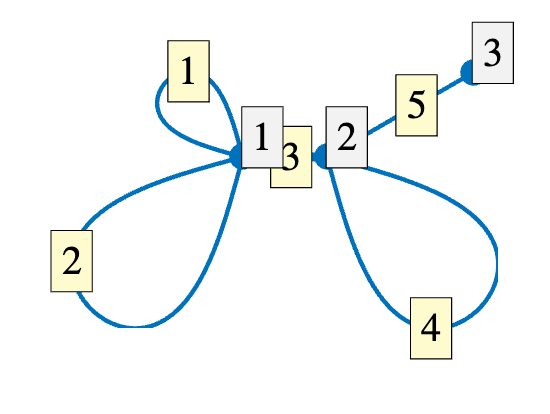

nx = [20 40; 16 32];
errors=zeros(1,2);
discretizations={'Uniform','Chebyshev'};
for j=1:2
    for k=1:2

Define the quantum graph (all that changes between the two iterates is the number of discretization points per unit length and the discretization).

        Phi=quantumGraph(s,t,L,'RobinCoeff',robinCoeff,'nxVec',nx(j,k),'Weight',weight,'Discretization',discretizations{j});
        Phi.addPlotCoords(@poissonExamplePlotCoords);
        Phi.addPotential(potentialV);
        if j*k==1; Phi.plot('layout'); end

Using the Uniform discretization:

The error with N=20 is 1.0246e-03.


The error with N=40 is 2.5579e-04.


The maximum error went down by a factor of 4.0056.


Using the Chebyshev discretization:

The error with N=16 is 1.8038e-07.


The error with N=32 is 1.5615e-12.


The maximum error went down by a factor of 115512.1118.


Set up the exact solution on the edges

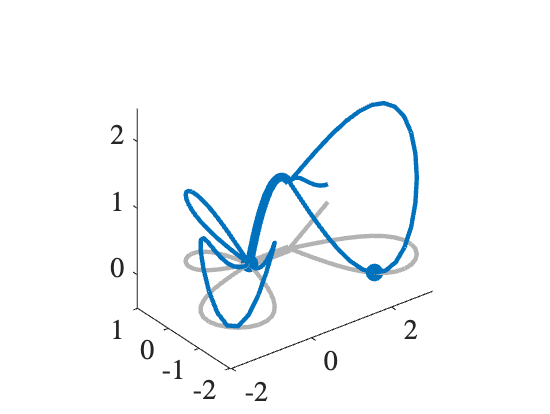

        exactSolution = Phi.applyFunctionsToAllEdges({u1,u2,u3,u4,u5});

Set up the nonhomogeneous data on the edges

        edgeData = Phi.applyFunctionsToAllEdges({f1,f2,f3,f4,f5});

Solve and compute errors

        numericalSolution = Phi.solvePoisson('edgeData',edgeData,'nodeData',nodeData);
        errors(k)= Phi.norm(exactSolution-numericalSolution,inf);
    end

Display the reduction in error. Since the discretization is second order, this should be about a factor of four.

    fprintf('Using the %s discretization:',discretizations{j})
    fprintf('The error with N=%i is %0.4d.\n',nx(j,1),errors(1))
    fprintf('The error with N=%i is %0.4d.\n',nx(j,2),errors(2))
    fprintf("The maximum error went down by a factor of %0.4f.\n", errors(1)/errors(2) )
end

Plot the solution

Phi.plot(numericalSolution)